warning off
init_deconvolution


Adding toolboxes and subfolders to path...

projectFolder = /net/store/nbp/users/behinger/projects/deconvolution/git


Adding toolboxes and subfolders to path... 


warning on

# Introduction

Subjects are exploring a face stimulus. Using an eyetracker and the EEG-Eye toolbox we add markers of saccade onsets into our EEG-Data. The data were cleaned for eye-movement related artefacts using ICA.

In this tutorial we try to disentangle stimulus related ERPs and microsaccade related ERPs.

PROJECTPATH = '/media/behinger/6ECEC8DFCEC8A127/deconvolution/application_microsaccades/';
EEG = pop_loadset('filename','msaff_15.set','filepath',sprintf('%s/02_sync_data_with_sacc',PROJECTPATH));

pop_loadset(): loading file /media/behinger/6ECEC8DFCEC8A127/deconvolution/application_microsaccades/02_sync_data_with_sacc/msaff_15.set ...


EEG = eeg_checkset(EEG);
% A simple threshold function taken from ERPLAB
winrej = dc_continuousArtifactDetect(EEG,'amplitudeThreshold',250);


	So, basicrap.m will be applied over the full range of data.

Please wait. This might take several seconds...

 91 segments were marked.



% We remove very noisy data segments (>250mV) from the designmatrix

# Defining the design

cfgDesign = [];
% Notice how we can group multiple stimuli into a single event
cfgDesign.eventtype = {'saccade',{'S121','S122','S123'}};
% We use intercept-only formulas because we are only interested in the overlap for now
cfgDesign.formula = {'y ~ 1','y~1'};
EEG = dc_designmat(EEG,cfgDesign);

Multiple events with separate model-formula detected


Modeling event(s) [saccade] using formula: y ~ 1 
Modeling event(s) [S121,S122,S123] using formula: y~1 


# Timeshift

In order to compensate for the inevitable linear overlap between ERPs, we want to use timeshifting / prepare the designmatrix for the deconvolution step. In this step we generate for each column of the designmatrix timeshifted (by t = 1, t=2, t=3 ...) and append them to the designmatrix.

cfgTimexpand = [];
cfgTimexpand.timelimits = [-.3,0.8];
cfgTimexpand.method = 'full';

EEG1 = dc_timeexpandDesignmat(EEG,cfgTimexpand);


dc_timeexpandDesignmat(): Timeexpanding the designmatrix...
...done


cfgTimexpand.method = 'fourier';
cfgTimexpand.timeshiftparam = 20; % use frequencies up to (dF = 1/T): 1/(1.1s) *20 ~ 18Hz
% effective parameters are here twice as high because each frequ. is defined by cos+sin
EEG2 = dc_timeexpandDesignmat(EEG,cfgTimexpand);


dc_timeexpandDesignmat(): Timeexpanding the designmatrix...
frequency resolution 1/T = 0.91 Hz 
rounding timeexpandparam from even 60 to odd 59 
Fourier basisfunctions: using DC + the lower frequencies up to 26.36 Hz (approximation) 
Convolving and adding row 1 from 2 to designmatrix 
Convolving and adding row 2 from 2 to designmatrix 
...done


cfgTimexpand.method = 'spline';
cfgTimexpand.timeshiftparam = 40; % use 40 splines over the 1.1s epoch (equivalent number of effective parameters as fourier)

EEG3 = dc_timeexpandDesignmat(EEG,cfgTimexpand);


dc_timeexpandDesignmat(): Timeexpanding the designmatrix...


cfg =          timelimits: [-0.3 0.8]
             method: 'splines'
     timeshiftparam: 40
    timeexpandparam: 30
             sparse: 1


Convolving and adding row 1 from 2 to designmatrix 
Convolving and adding row 2 from 2 to designmatrix 
...done




dc_plotDesignmat(EEG1,'timeexpand',1)

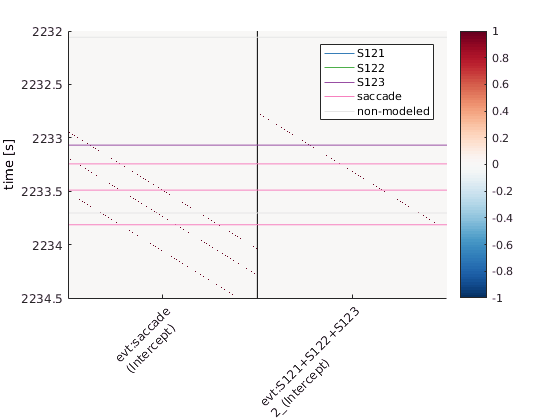

ylim([2232 2234.5])

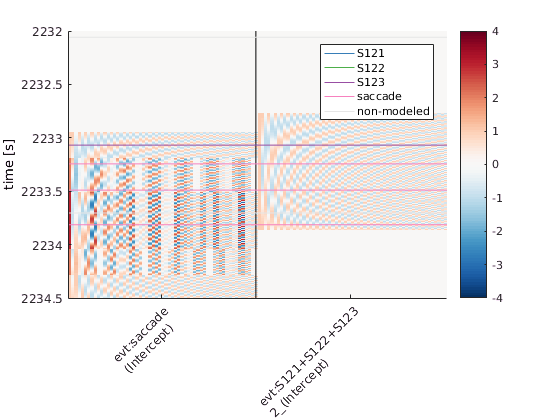

dc_plotDesignmat(EEG2,'timeexpand',1)
ylim([2232 2234.5])

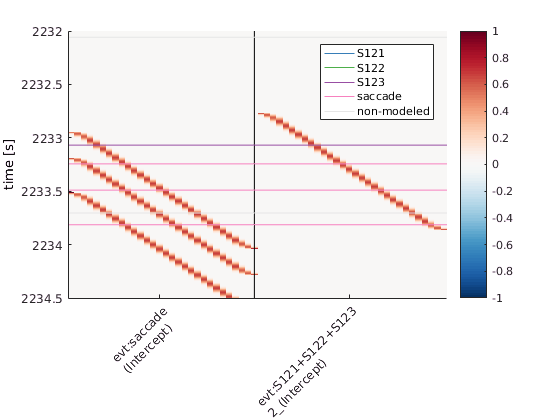

dc_plotDesignmat(EEG3,'timeexpand',1)
ylim([2232 2234.5])

# Cleaning of data

EEG1 = dc_continuousArtifactExclude(EEG1,struct('winrej',winrej));


removing 11.5% from design matrix (fill it with zeros) 


EEG2 = dc_continuousArtifactExclude(EEG2,struct('winrej',winrej));


removing 11.5% from design matrix (fill it with zeros) 


EEG3 = dc_continuousArtifactExclude(EEG3,struct('winrej',winrej));


removing 11.5% from design matrix (fill it with zeros) 


# Fit the deconvolution model

EEG1= dc_glmfit(EEG1,'channel',[32]);


dc_glmfit(): Fitting deconvolution model...solving the equation system

solving electrode 32 (of 1 electrodes in total)... 19 iterations, took 1.4s
 LMfit finished 


EEG2= dc_glmfit(EEG2,'channel',[32]);


dc_glmfit(): Fitting deconvolution model...solving the equation system

solving electrode 32 (of 1 electrodes in total)... 19 iterations, took 23.7s
 LMfit finished 


EEG3= dc_glmfit(EEG3,'channel',[32]);


dc_glmfit(): Fitting deconvolution model...solving the equation system

solving electrode 32 (of 1 electrodes in total)... 44 iterations, took 3.5s
 LMfit finished 


# Plot the results

We choose a single electrode and plot all effects.

unfold1= dc_beta2unfold(EEG1);
unfold2= dc_beta2unfold(EEG2);
unfold3= dc_beta2unfold(EEG3);

% Our plotting function allows for arbitrary additional fields
% as long as they have the same size as unfold.beta
unfold = unfold1;
unfold.fourier = unfold2.beta;
unfold.spline= unfold3.beta;
display(unfold)

unfold =       deconv: [1×1 struct]
        beta: [48×550×2 double]
       times: [1×550 double]
    chanlocs: [1×48 struct]
       param: [1×2 struct]
     fourier: [48×550×2 double]
      spline: [48×550×2 double]


plotting all parameters


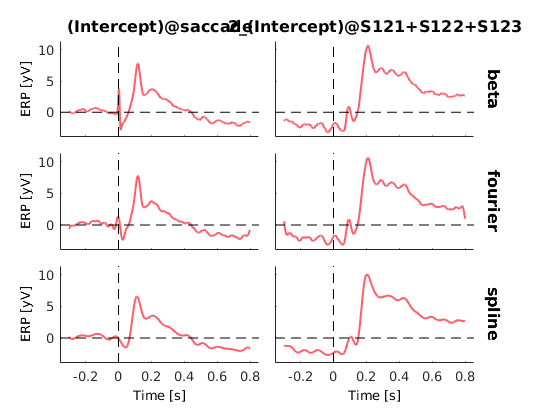

dc_plotParam(unfold,'channel',32);

The first model has 550 parameter per predictor, the second and third one only 40 per predictor. This can show up in memory performance for large models. But due to the great sparseness of the first model (the stick-functions), it is actually often the fastest one..